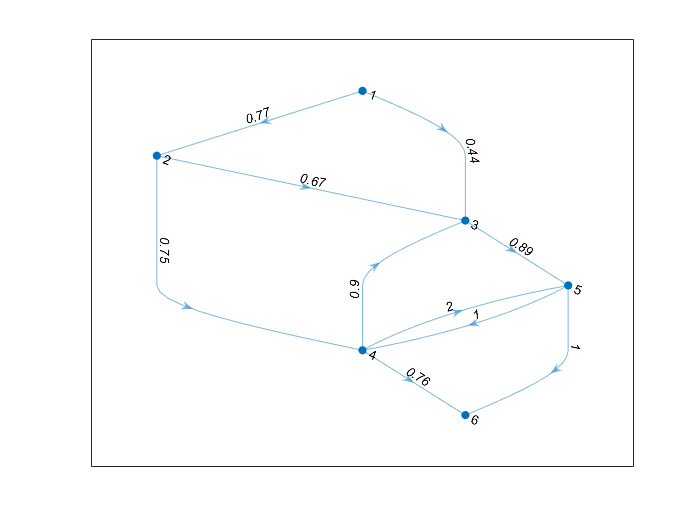

%博客案例一
s = [1 1 2 2 3 4 4 4 5 5];
t = [2 3 3 4 5 3 5 6 4 6];
weights = [0.77 0.44 0.67 0.75 0.89 0.90 2 0.76 1 1];
G = digraph(s,t,weights);
plot(G,'EdgeLabel',G.Edges.Weight,'Layout','layered');

mf = maxflow(G,1,6)

mf = 1.2100

%博客案例二
s = [1 1 2 2 3 3 4];
t = [2 3 3 4 4 5 5];
weights = [10 6 15 5 10 3 8];
G = digraph(s,t,weights);
H = plot(G,'EdgeLabel',G.Edges.Weight);
[mf,GF] = maxflow(G,1,5,'augmentpath')

mf = 11

GF =   digraph - 属性:

    Edges: [6×2 table]
    Nodes: [5×0 table]


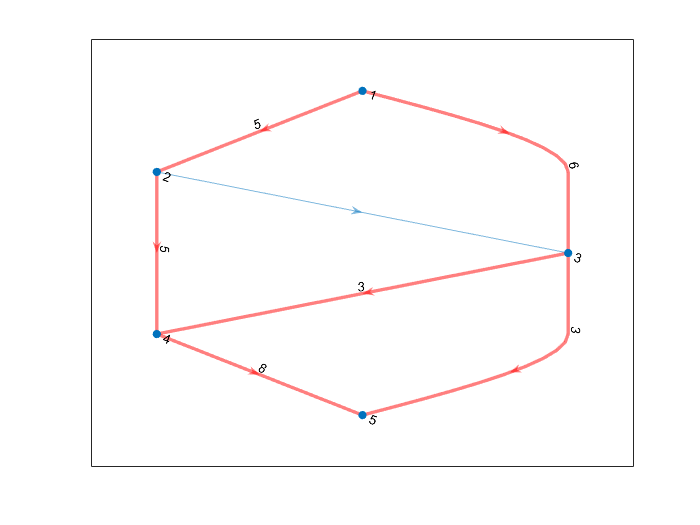

H.EdgeLabel = {};
highlight(H,GF,'EdgeColor','r','LineWidth',2);
st = GF.Edges.EndNodes;
labeledge(H,st(:,1),st(:,2),GF.Edges.Weight);

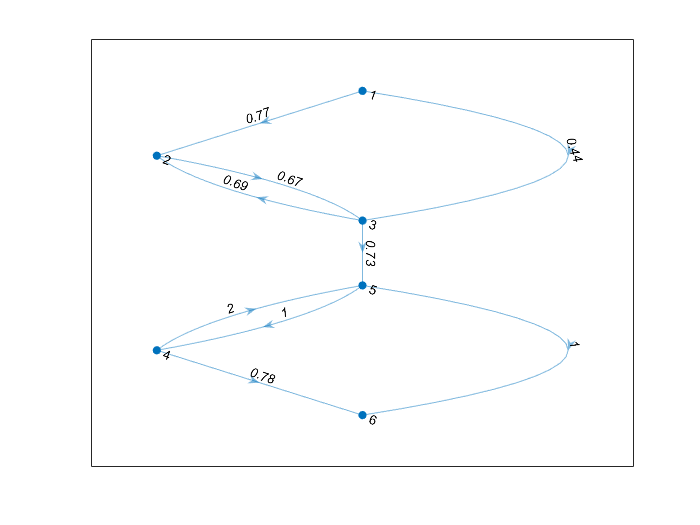

%博客案例三
s = [1 1 2 3 3 4 4 5 5];
t = [2 3 3 2 5 5 6 4 6];
weights = [0.77 0.44 0.67 0.69 0.73 2 0.78 1 1];
G = digraph(s,t,weights);
plot(G,'EdgeLabel',G.Edges.Weight,'Layout','layered')

[mf,~,cs,ct] = maxflow(G,1,6)

mf = 0.7300

cs =      1
     2
     3


ct =      4
     5
     6


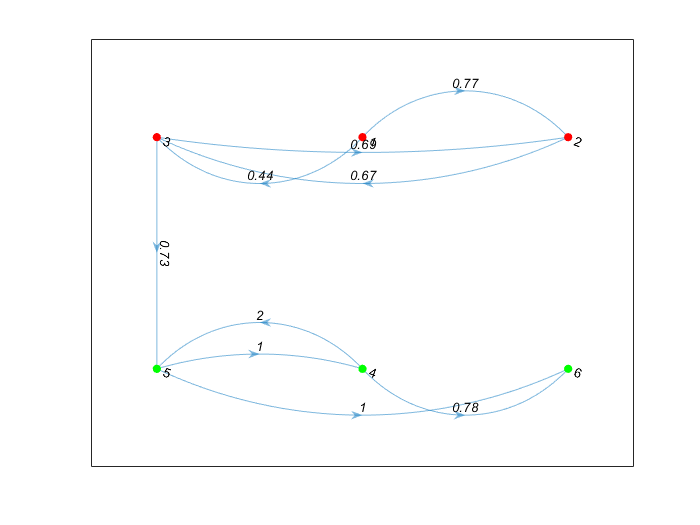

H = plot(G,'Layout','layered','Sources',cs,'Sinks',ct, ...
    'EdgeLabel',G.Edges.Weight);
highlight(H,cs,'NodeColor','red')
highlight(H,ct,'NodeColor','green')